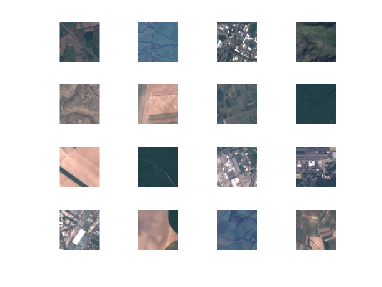

unzip('small_EUROSat.zip');
imds = imageDatastore('small_EUROSat', ...
    'IncludeSubfolders',true, ...
    'LabelSource','foldernames');
% digitDatasetPath = fullfile(small_EUROSat,'toolbox','nnet','nndemos', ...
%     'nndatasets','DigitDataset');
% imds = imageDatastore(digitDatasetPath, ...
%     'IncludeSubfolders',true,'LabelSource','foldernames');
% 划分验证集和训练集
[imdsTrain,imdsValidation] = splitEachLabel(imds,0.7,'randomized');

% 随机显示训练集中的部分图像
numTrainImages = numel(imdsTrain.Labels);
idx = randperm(numTrainImages,16);
figure
for i = 1:16
    subplot(4,4,i)
    I = readimage(imdsTrain,idx(i));
    imshow(I)
end


%% 步骤2：加载预训练好的网络

% 加载alexnet网络（注：该网络需要提前下载，当输入下面命令时按要求下载即可）
%net = alexnet;
net=alexnet

net =   SeriesNetwork with properties:

         Layers: [25×1 nnet.cnn.layer.Layer]
     InputNames: {'data'}
    OutputNames: {'output'}


Training on single CPU.
Initializing input data normalization.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |   Accuracy   |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:07 |        6.67% |       20.95% |       2.7061 |       2.2614 |      5.0000e-05 |
|       1 |           3 |       00:00:14 |        6.67% |       27.62% |       3.9910 |       2.1567 |      5.0000e-05 |
|       1 |           6 |       00:00:21 |       20.00% |       34.76% |       2.7144 |       1.8978 |      5.0000e-05 |
|       1 |           9 |       00:00:29 |       13.33% |       42.38% |       2.2581 |   

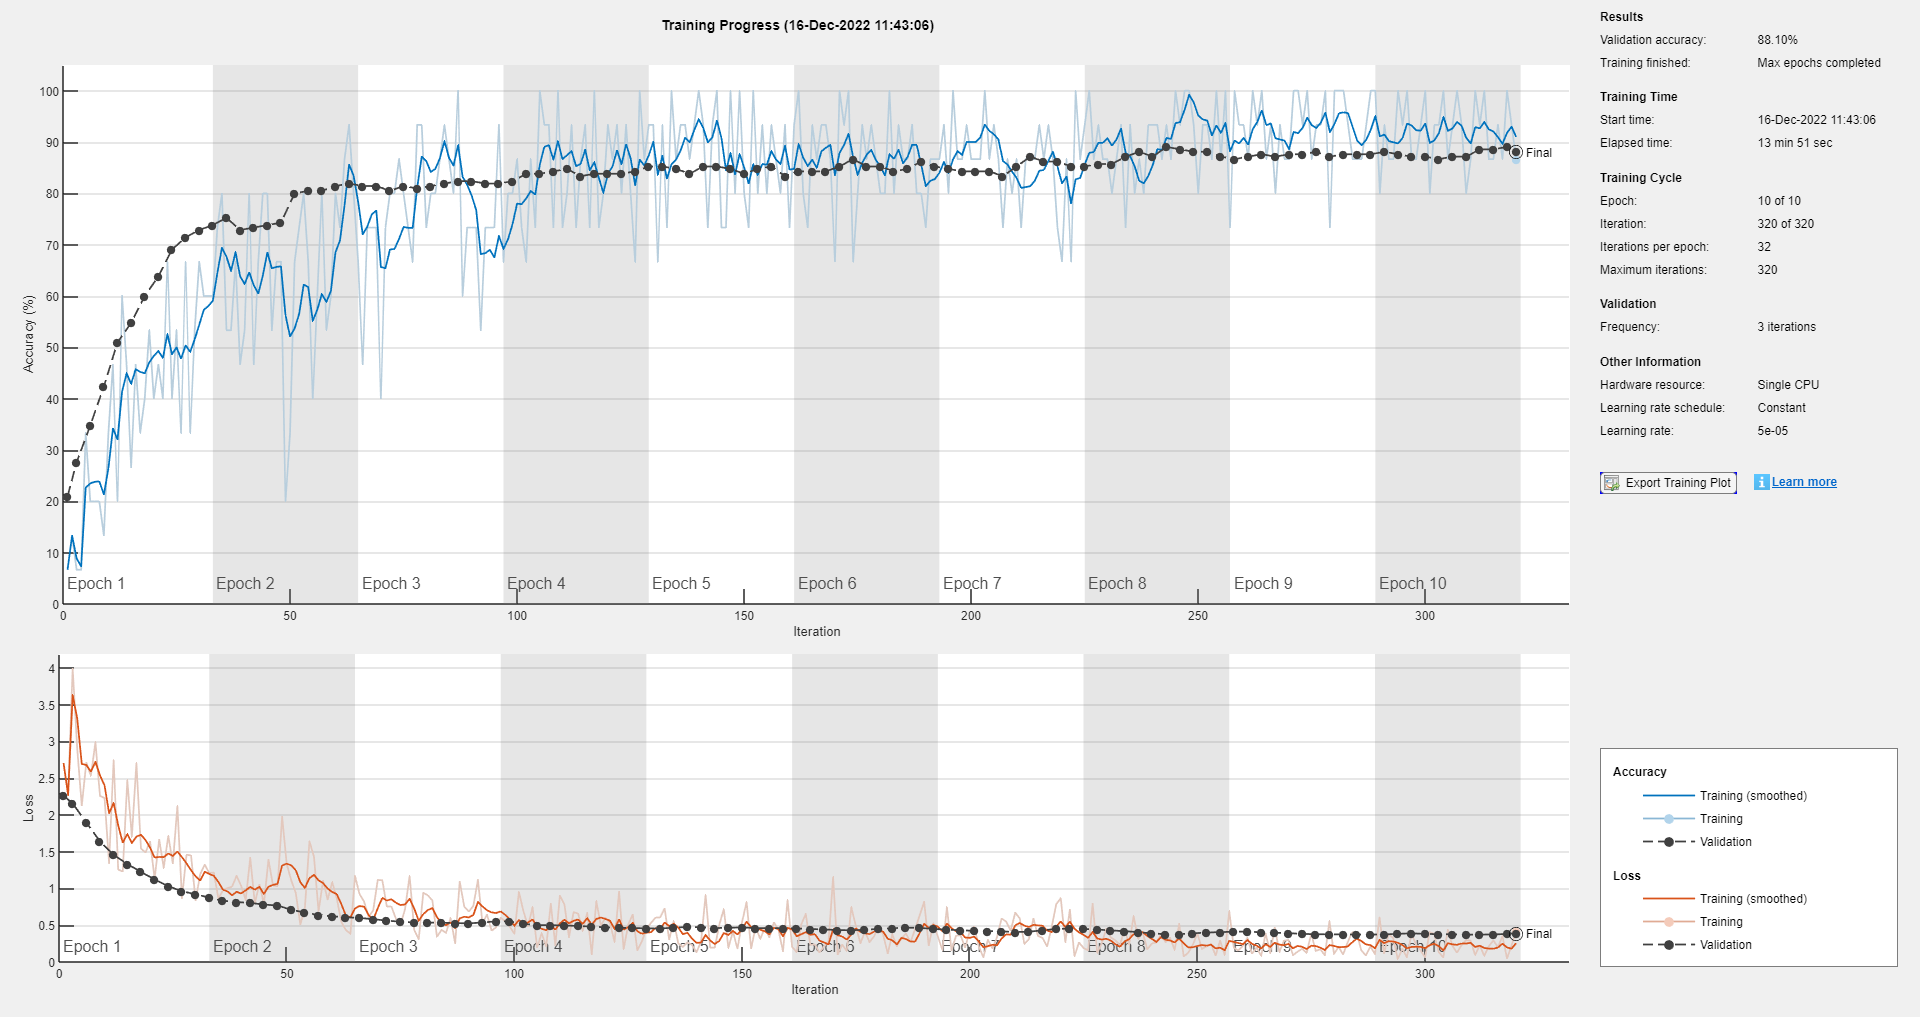

%% 步骤3：对网络结构进行改进

% 保留AlexNet倒数第三层之前的网络
layersTransfer = net.Layers(1:end-3);

% 确定训练数据中需要分类的种类
numClasses = numel(categories(imdsTrain.Labels));

% 构建新的网络，保留AlexNet倒数第三层之前的网络，在此之后重新添加了全连接
layers = [
    layersTransfer                                       % 保留AlexNet倒数第三层之前的网络
    fullyConnectedLayer(numClasses)                      % 将新的全连接层的输出设置为训练数据中的种类
    softmaxLayer                                         % 添加新的Softmax层
    classificationLayer ];                               % 添加新的分类层

%% 步骤4：调整数据集

% 查看网络输入层的大小和通道数
inputSize = net.Layers(1).InputSize;

% 将训练图像的大小调整为与输入层的大小相同
augimdsTrain = augmentedImageDatastore(inputSize(1:2),imdsTrain);
% 将验证图像的大小调整为与输入层的大小相同
augimdsValidation = augmentedImageDatastore(inputSize(1:2),imdsValidation);

%% 对网络进行训练

% 对训练参数进行设置
options = trainingOptions('sgdm', ...
    'MiniBatchSize',15, ...
    'MaxEpochs',10, ...
    'InitialLearnRate',0.00005, ...
    'Shuffle','every-epoch', ...
    'ValidationData',augimdsValidation, ...
    'ValidationFrequency',3, ...
    'Verbose',true, ...
    'Plots','training-progress');

% 用训练图像对网络进行训练
    netTransfer = trainNetwork(augimdsTrain,layers,options);

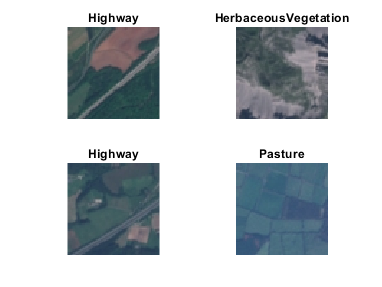

    
%% 分类验证图像并并随机显示分类结果

% 对训练好的网络采用验证数据集进行验证
[YPred,scores] = classify(netTransfer,augimdsValidation);

% 随机显示验证效果
idx = randperm(numel(imdsValidation.Files),4);
figure
for i = 1:4
    subplot(2,2,i)
    I = readimage(imdsValidation,idx(i));
    imshow(I)
    label = YPred(idx(i));
    title(string(label));
end


%% 计算分类准确率
YValidation = imdsValidation.Labels;
accuracy = mean(YPred == YValidation)

accuracy = 0.8810

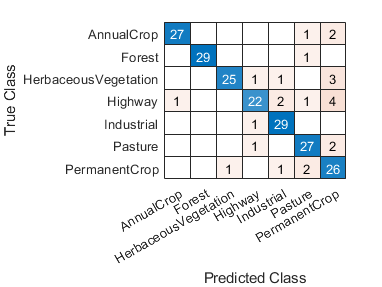


%% 创建并显示混淆矩阵
figure
confusionchart(YValidation,YPred)